# **This live script aim to expalin some approaches attempted by the team that we gave up.**

**One of our first approach was trying edge detection to detect weeds in images but this idea has been quickly abandonned. We tried with several modifications but converting images to grayscales made it nearly impossible to get weeds and lettuces edges correctly.**

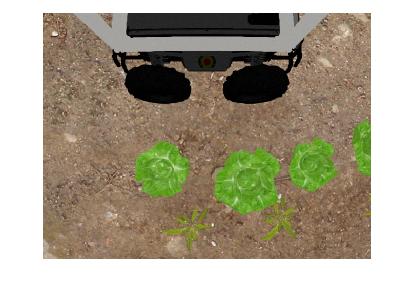

% Read the image
image = imageList{4};
imshow(image);

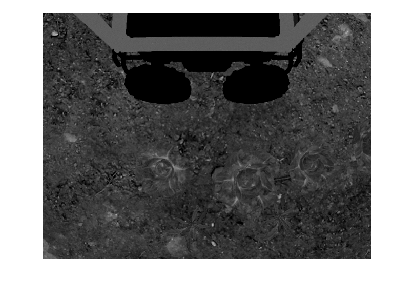


% Convert the image to grayscale
grayImage = rgb2gray(image);
grayImage = grayImage - 70;
imshow(grayImage);

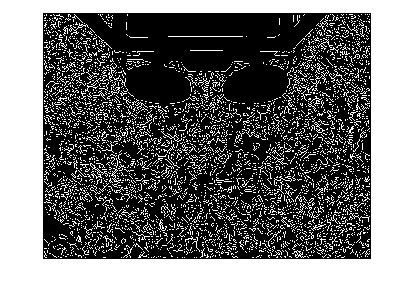


% Apply edge detection
edgeImage = edge(grayImage, 'Canny');
imshow(edgeImage);

**Another approach was to use histograms for detection, taking a reference image and computing his histogram. We were going to divide future camera images in different fragments with the same size as the reference image in order to calculate their histograms and evaluate similarity between these histograms.**

**Abandonned (not enough precise and very time consuming)**

% Load the reference image (ROI)
refImage = imread('weed.jpg');

% Calculate the histogram of the reference image for each color channel
refHistogramR = imhist(refImage(:,:,1));
refHistogramG = imhist(refImage(:,:,2));
refHistogramB = imhist(refImage(:,:,3));

% Set a threshold for histogram similarity
threshold = 0.9;

% Load the sample image
sampleImage = imread('right_sample.png');

% Initialize an array to store the detected locations
detectedLocations = [];

% Define the search window size (should match the size of the reference image)
windowSize = size(refImage);

% Iterate over the sample image using a sliding window approach
for y = 1 : size(sampleImage, 1) - windowSize(1)
    for x = 1 : size(sampleImage, 2) - windowSize(2)
        % Extract the current window from the sample image
        window = sampleImage(y : y+windowSize(1)-1, x : x+windowSize(2)-1, :);
        
        % Calculate the histogram of the current window for each color channel
        windowHistogramR = imhist(window(:,:,1));
        windowHistogramG = imhist(window(:,:,2));
        windowHistogramB = imhist(window(:,:,3));
        
        % Calculate the histogram intersection similarity for each color channel
        similarityR = sum(min(refHistogramR, windowHistogramR)) / sum(refHistogramR);
        similarityG = sum(min(refHistogramG, windowHistogramG)) / sum(refHistogramG);
        similarityB = sum(min(refHistogramB, windowHistogramB)) / sum(refHistogramB);
        
        % Calculate the overall similarity as the average of the color channel similarities
        overallSimilarity = (similarityR + similarityG + similarityB) / 3;
        
        % Check if the overall similarity meets the threshold
        if overallSimilarity >= threshold
            % Store the detected location
            detectedLocations = [detectedLocations; x, y];
        end
    end
end

% Display the sample image with detected locations marked
figure;
imshow(sampleImage);
hold on;
for i = 1 : size(detectedLocations, 1)
    rectangle('Position', [detectedLocations(i, 1), detectedLocations(i, 2), windowSize(2), windowSize(1)], 'EdgeColor', 'r', 'LineWidth', 2);
end
hold off;
